 PROBLEMA 1

 = $\frac{2}{\pi }\int_{-1}^1 \frac{f\left(x\right)T_k \left(x\right)}{\sqrt{1-x^2 }}\mathrm{dx}$

(a) Sa se calculeze $\int_{-1}^1 T_{k\left(\right.} \left(x\right)\mathrm{dx}$

Polinoamele Cebisev de speta I sunt definite prin:


$$T_k \left(x\right)=\cos \left(k*\arccos \left(x\right)\right),\mathrm{pentru}\;x\in \left\lbrack -1,1\right\rbrack$$


Vrem sa calculam:


$$I_k =\int_{-1}^1 T_k \left(x\right)\mathrm{dx}=\int_{-1}^1 \cos \left(k*\arccos \left(x\right)\right)\mathrm{dx}$$


Folosim

x = cos θ ⇒ dx = -sinθ dθ 

Cand x = −1 ⇒ θ = π

Cand x = 1 ⇒ θ = 0

Asadar:


$$\int_{-1}^1 T_{k\;} \left(x\right)\;\mathrm{dx}=\int_{\pi }^0 \cos \left(k_{\theta } \right)\left(-\sin \theta \right)d\theta =\int_0^{\pi } \cos \left(k_{\theta } \right)\;\sin \theta \;d\theta$$


De unde ne rezulta


$$\int_0^{\pi } \cos \left(k_{\theta } \sin \theta \right)d\theta =\left\lbrace \begin{array}{ll}
0 & ,k\;e\;\mathrm{impar}\\
\frac{2}{1-k^2 } & ,k\;e\;\mathrm{par}
\end{array}\right.$$


% b
n_max = 6;
ck = sym('c', [1 n_max+1]);
cuadratura = 0;

for k_val = 0:n_max
    if mod(k_val, 2) == 0
        if k_val == 0
            term = 2 * ck(k_val+1);
        else
            term = 2 * ck(k_val+1) / (1 - k_val^2);
        end
        cuadratura = cuadratura + term;
    end
end

disp('Formula de cuadratura:');

Formula de cuadratura:


disp(cuadratura);

$$2\,c_{1}-\frac{2\,c_{3}}{3}-\frac{2\,c_{5}}{15}-\frac{2\,c_{7}}{35}$$



% c
function vi = Cheb1quad(f, precizie)
max_iter = 100;
vi_old = 0;

for n = 2:2:max_iter % pasi pari 
    % noduri
    x = cos(pi * ((1:n) - 0.5) / n)';
    
    % coeficienti
    c = zeros(1, n);
    for k = 0:n-1
        T_k = cos(k * acos(x));
        c(k+1) = (2/n) * sum(f(x) .* T_k);
    end
    
    % formula de cuadratura
    integral = 0;
    for k = 0:n-1
        if mod(k, 2) == 0 %k - par
            if k == 0
                integral = integral + c(1);
            else
                integral = integral + 2 * c(k+1) / (1 - k^2);
            end
        end
    end
    
    % verificare convergenta
    if abs(integral - vi_old) < precizie
        vi = integral;
        return;
    end
    vi_old = integral;
end

vi = integral;
end

f = @(x) exp(x).*cos(x);
precizie = 1e-8;

I_aprox = Cheb1quad(f, precizie);
I_exact = integral(f, -1, 1);

fprintf('Aproximare:      %.15f\n', I_aprox);

Aproximare:      1.933421496199802


fprintf('Valoare exactă:  %.15f\n', I_exact);

Valoare exactă:  1.933421496200713


fprintf('Eroare absolută: %.2e\n', abs(I_aprox - I_exact));

Eroare absolută: 9.11e-13


PROBLEMA 2

a) ${\left(F^{-1} \right)}^{\prime } \left(\alpha \right)=\frac{1}{F^{\prime } \left(\alpha \right)}$  , iar cum $F^{\prime } \left(\alpha \right)$>1 => ${\left(F^{-1} \right)}^{\prime } \left(\alpha \right)$<1  => converge spre $\alpha$.

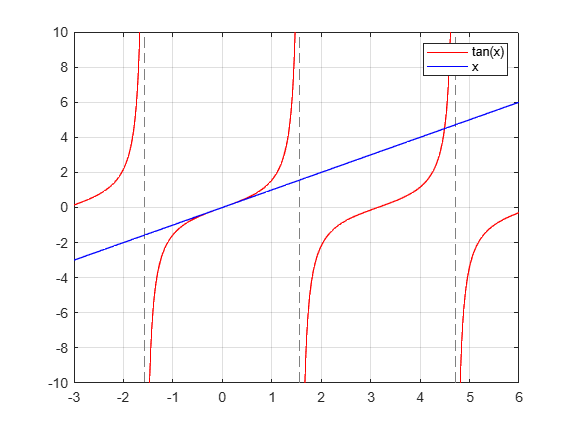

%b)
syms x
g=@(x) atan(x)+pi;

figure;
fplot(@tan, [-pi, 2*pi], 'r');
hold on;
fplot(@(x) x, [-pi, 2*pi], 'b');
grid on;
legend('tan(x)', 'x');
axis([-3 6 -10 10]);


[x_1,val,i]=aproximare_succesiva(g,0,1e-8,500)

x_1 = 4.4934

val = 4.4934

i = 8

abs(x_1-tan(x_1))

ans = 2.0291e-08


function [x1, val_f, i] = aproximare_succesiva(f, x0, err, NrMaxIt) %laborator
    x = zeros(1, NrMaxIt);
    x(1) = x0;

    for i = 1:NrMaxIt

        x(i+1) = f(x(i));

        if norm(f(x(i+1)), Inf) < err || norm(x(i+1) - x(i), Inf) < err ...
                || norm(x(i+1) - x(i), Inf) / norm(x(i+1), Inf) < err
            x1 = x(i+1);
            val_f = f(x1);
            return;
        end
    end

    x1 = x(end);
    val_f =f(x1);
end